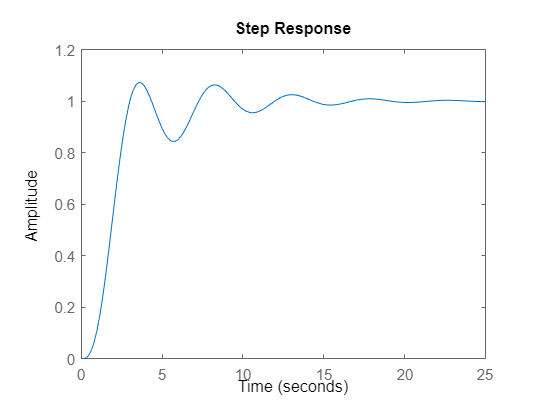

%% Define system dynamics
% Define variables
ks = 1;
Jl = 1;
Jm = 1;
b = 1;

A = [0 1 0 0; -ks/Jl 0 ks/Jl 0; 0 0 0 1; ks/Jm 0 -ks/Jm -b/Jm];
B = [0; 0; 0; 1/Jm];
C = [0 1 0 0];
D = 0;

% Create object for the dynamical system
sys = ss(A,B,C,D);

%% Simulate the system
figure
step(sys)

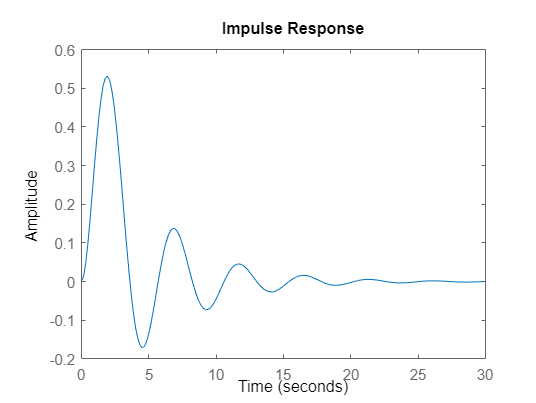

figure
impulse(sys)

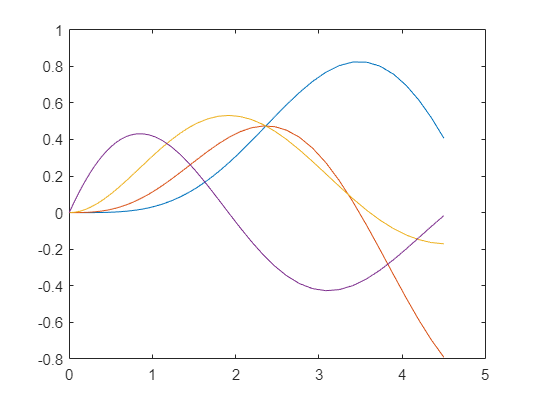


tEnd = 10; % End time of simulation
x0 = [0; 0; 0; 0]; % Initial condition
% Specification of input
tu = (0:0.01:5)';
u = cos (tu);
% Simulate the system
options = []; % Sol veroptions (can be changed with odeset)
[tSim, xSim] = ode45(@sysDesc, [0 tEnd ], x0, options, [tu u], sys);
%Plot result
figure; plot(tSim, xSim)


[num, den] = tfdata(sys);
num

num = 1×1 cell array
    {[0 0 0 1 0]}


den

den = 1×1 cell array
    {[1 1.0000 2.0000 1.0000 -5.7253e-17]}


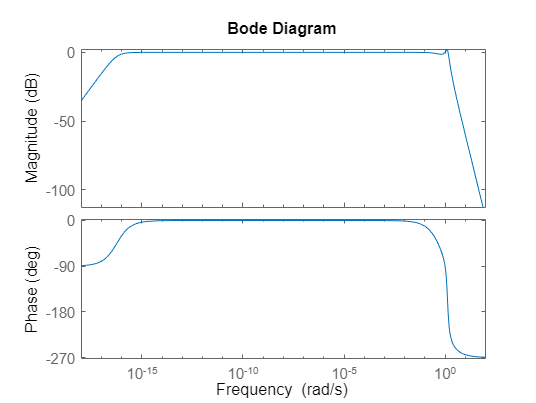


bode(sys)

function dxdt = sysDesc(t,x,u,sys)
    u = interp1(u(:,1),u(:,2),t);
    dxdt= sys.A*x+sys.B*u;
end
